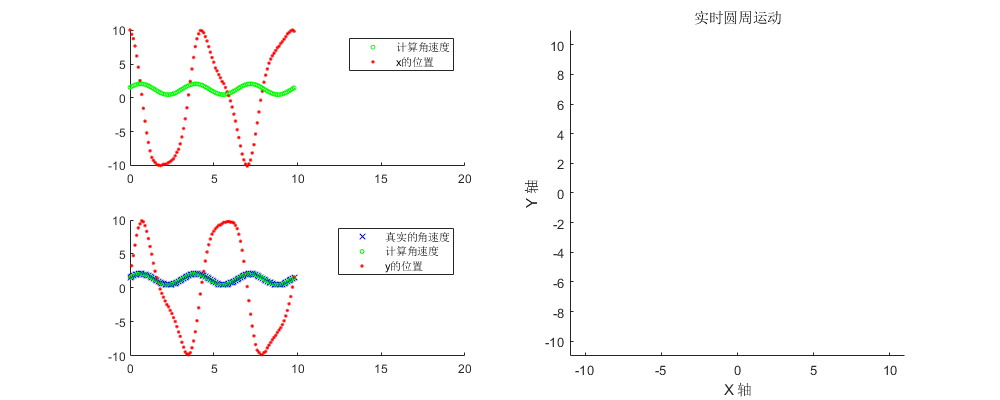

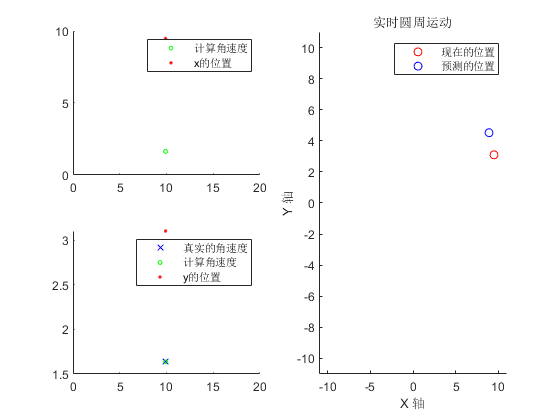

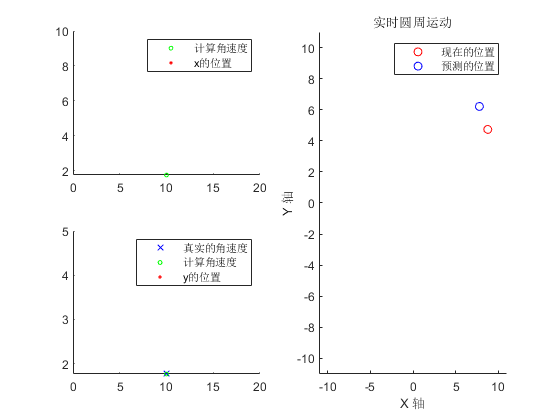

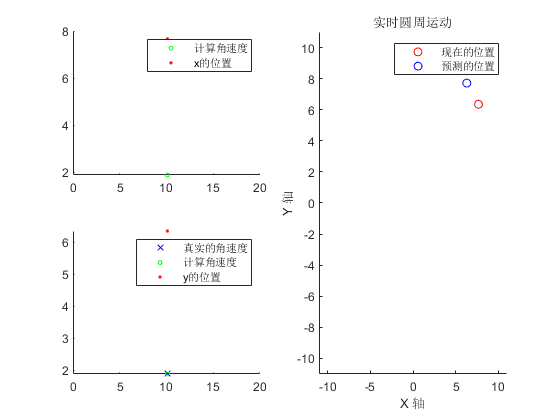

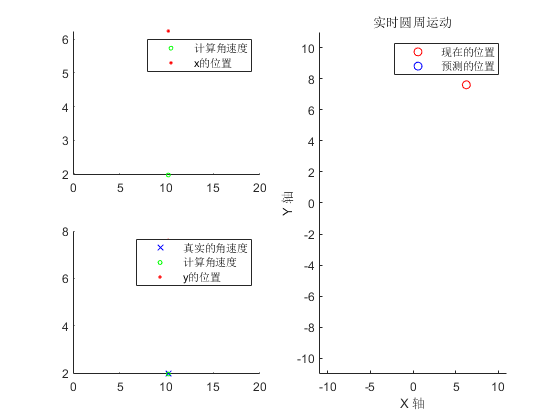

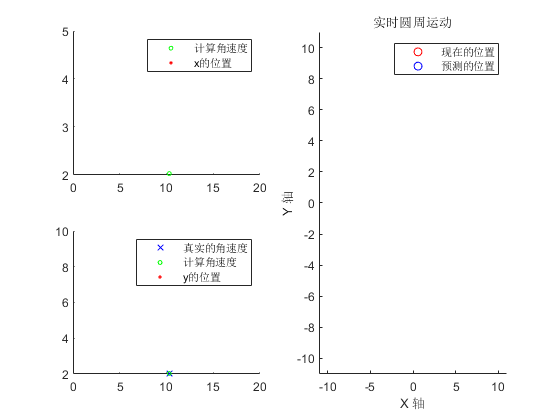

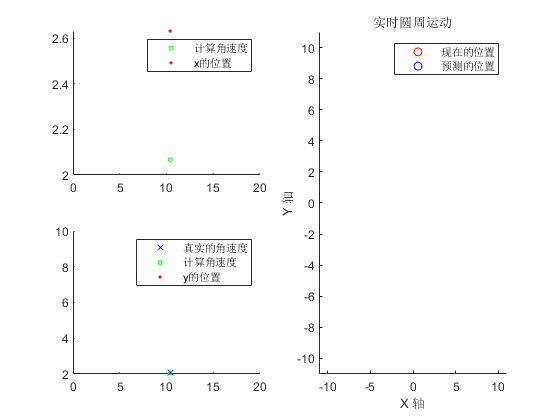

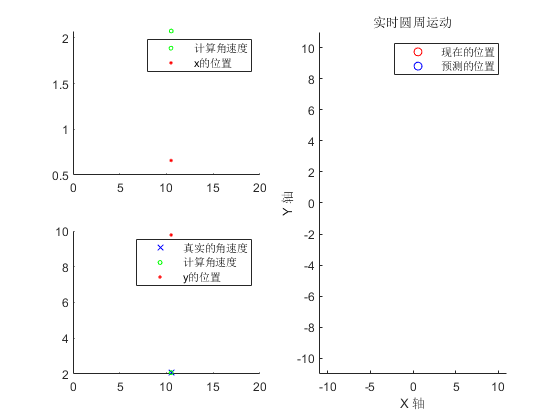

错误使用 matlab.graphics.axis.Axes/get
运算被用户终止。

出错 title (line 63)
   h = get(ax,'Title');

clc
clear 
close all
opengl hardware
pred_time = 0.1;
% 参数设置 下面参数都是能量机关的参数，除半径不是
radius = 10;            % 圆的半径
a = (1.045-0.780)*rand() + 0.780;
w = (2-1.884)*rand() + 1.884;
true_f = w/(2*pi);
b = 2.090 - a;
theta_rand = randn();
angular_velocity = @(t)a*sin(w*t+ theta_rand)+b;  % 角速度（弧度/秒）
% angular_velocity =@(t) 1; % 匀角速度时
dt = 0.1;       % 时间步长（秒）
time_duration = 20;    % 运动持续时间（秒）

rotation_angle = 1*(pi / 16);  % 能量机关绕X轴旋转的角度（22.5度）也就是你仰视看能量机关

% 初始化位置
x0 = radius;% 对应theta = 0

y0 = 0;
vx = 0;
vy = 0;
% 创建一个指定大小的绘图窗口
figure('Position', [100, 100, 1000, 400]); % [左上角x, 左上角y, 宽度, 高度]
% 创建一个空矩阵，用于存储轨迹点的坐标
trajectory = [];
x_data = [];
y_data = [];
t_data = [];
v_data = [];
% 进行动画循环
for t = 0:dt:time_duration-dt
    if length(t_data)==length(0:dt:time_duration/2-dt)
        t_data(1)=[];
        v_data(1)=[];
        x_data(1)=[];
        y_data(1)=[];
    end
    % 计算下一个时间点的位置
    x = x0*cos(angular_velocity(t) * dt) - y0*sin(angular_velocity(t) * dt);
    y = y0*cos(angular_velocity(t) * dt) + x0*sin(angular_velocity(t) * dt);
    rotation_matrix = [1, 0, 0; 0, cos(rotation_angle), -sin(rotation_angle); 0, sin(rotation_angle), cos(rotation_angle)];
    rotated_point = rotation_matrix * [x; y; 0];
%     v = (acos(x/radius) - acos(x0/radius))/dt;
    vx = (x-x0)/dt;
    vy = (y-y0)/dt;
    v = (1 / (x^2+y^2)) * (x * vy - y * vx);
    v_data = [v_data, v];
    x0 = x;
    y0 = y;
    x = rotated_point(1)+ 0.05*randn();
    y = rotated_point(2)+ 0.05*randn();
    
    % 将当前位置添加到轨迹矩阵中
    trajectory = [trajectory; [x, y]];
    
    % 将当前位置和时间添加到数据向量中
    x_data = [x_data, x];
    y_data = [y_data, y];
    t_data = [t_data, t];
    

    if t>=time_duration/2 -dt
        % 计算傅里叶变换
        L = length(t_data);
        Fs = 1/dt;
        yy_t = fft(v_data);
        yout = 2*abs(yy_t(1:L/2))/L;
        phases = angle(yy_t(1:L/2));
        frequencies = Fs * (0:(L/2-1)) / L;
        figure;
        stem(frequencies,yout)
        % 找到除直流分量的最大振幅和对应的索引
        [amplitudes_max_target_frequencies, target_max_indices] = max(yout(1,2:end), [], 2);
        
        threshold = amplitudes_max_target_frequencies*0.5;
        values_above_threshold = yout(1, 2:end) > threshold;
        indices_above_threshold = find(values_above_threshold);
        indices_above_threshold = indices_above_threshold + 1;
        target_frequencies = [];
        for i = 1:1:length(indices_above_threshold)
            target_frequencies = [target_frequencies, frequencies(1,indices_above_threshold(i))];
        end
        amplitudes_at_target_frequencies = yout(1,indices_above_threshold);
        
        combined_period = 1/frequencies(target_max_indices+1);
        
        phases_target = phases(indices_above_threshold);
        targety = @(x) amplitudes_at_target_frequencies.*cos(2*pi*x*target_frequencies+phases_target);
        
        %% 线性回归趋势
        X = t_data';
        Y = v_data';
        di_f = int32(combined_period/(dt*2));
        [di_x,di_y] = caiyang2(X,Y,di_f);
        if mod(size(di_x,1), 2)~=0
            di_x(end,:) = [];
            di_y(end,:) = [];
        end
        
        di_newx = (0:dt:di_x(end,1))';
        di_newy = interp1(di_x, di_y, di_newx, 'linear');
        
        
%         figure;
        mdl = fitlm(di_newx, di_newy); 
%         disp(mdl)
        coefficients = mdl.Coefficients.Estimate;
%         plot(X,Y,"g-",di_newx,di_newy,"r-",di_newx,di_newx*coefficients(2)+coefficients(1),"b-")
%         plot(X,Y,"r-",di_newx,di_newx*coefficients(2)+coefficients(1),"b-")
        
        
        % % 显示提取的振幅
%         fprintf('频率为%f的振幅：%f\n',target_frequencies(1), amplitudes_at_target_frequencies(1));
        pred_t = [t_data(100),t_data(100) + pred_time];
        tar = targety(pred_t');
        targetynum = pred_t'*coefficients(2)+coefficients(1);
        for i =1:1:size(tar,2)
            targetynum = targetynum + tar(:,i);
        end
        pred_v = (targetynum(1)+targetynum(2))/2;
        pred_x = x*cos(pred_v * pred_time) - y*sin(pred_v * pred_time);
        pred_y = y*cos(pred_v * pred_time) + x*sin(pred_v * pred_time);
%         plot(t_data,v_data,"ro-",t_data,targetynum',"b-")
    end
 
    % 更新子图1
    subplot(2, 2, 1);
    hold on;
    plot(t, v, 'go','LineWidth', 0.2, 'MarkerSize', 3);
    plot(t,x,"r.")
    hold off;
    legend("计算角速度","x的位置")
    xlim([0, time_duration]);
    
    % 更新子图2
    subplot(2, 2, 3);
    hold on;
    plot(t,angular_velocity(t),"bx", 'LineWidth', 0.1)
    plot(t, v, 'gO','LineWidth', 0.2, 'MarkerSize', 3);
    plot(t,y,"r.")
    hold off;
    legend("真实的角速度","计算角速度","y的位置")
    xlim([0, time_duration]);
    
    % 更新轨迹图
    subplot(2, 2, [2, 4]);
    hold on;

    if t>=time_duration/2 -dt
        plot(x, y, 'rO');
        plot(pred_x,pred_y,'bO')
        hold off;
        axis([-radius - 1, radius + 1, -radius - 1, radius + 1]);
        xlabel('X 轴');
        ylabel('Y 轴');
        legend("现在的位置","预测的位置")
        title('实时圆周运动');
    else
        hold off;
        axis([-radius - 1, radius + 1, -radius - 1, radius + 1]);
        xlabel('X 轴');
        ylabel('Y 轴');
        title('实时圆周运动');
    end
    drawnow;  % 更新绘图窗口

end
    % 等待10s 傅里叶拟合10s效果很好，可以看到蓝色超前红色0.1s，因为我预测了0.1s的状态，上次蓝色的位置和红色重合
    % 匀速的就看完了
    % 下面是变速的
    % 我加了5%的随机噪声，和能量机关倾斜22.5度，发现对预测影响不大
    % dt为0.1但理论上为0.02左右，因为我们识别一帧20ms左右，也可能10ms，但是我电脑画不了那么多点，会卡主，根据采样定理，你采样频率大于实际频率2倍，就不影响结果，可以看到效果还是可以的，对于变速的效果也很好。
hold off;